# SysMIC M1: Assignment 5

If you need help for this assignment please make use of the [session 5 forum](http://sysmic.ac.uk/moodle/mod/forum/view.php?id=2529) .

When completed please save and upload here: [http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2403.](http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2403.) 

After submission you can access model answers via the [session 5 review](http://sysmic.ac.uk/moodle/mod/quiz/view.php?id=3201) activity.

`Name: [ Jade Lau ]`

## Exercise 1.1.5 

([section link](https://sysmic.ac.uk/textbook/1.1-bacterial-growth-1.html#1.1.2))

1. A single cell of E-coli divides every 15 minutes. Write a loop to generate population values over a thee hour period and plot them on a graph.

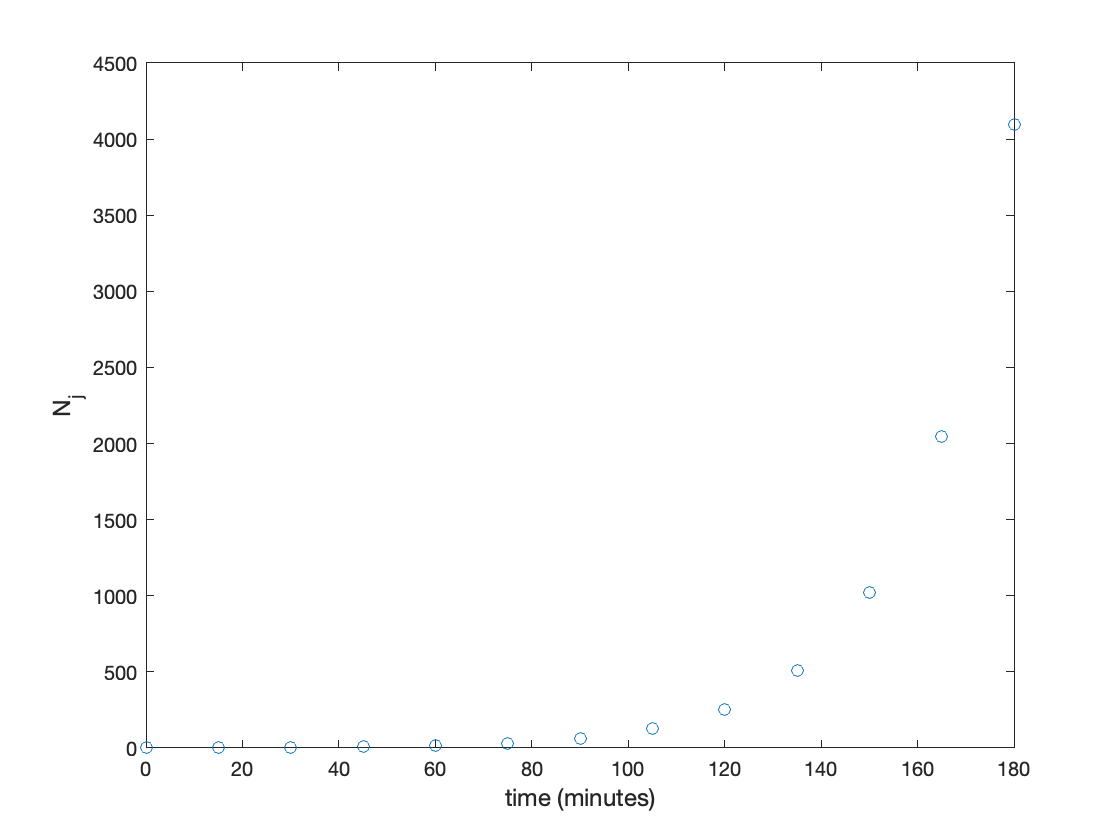

t = 0:15:180; 
nt = length(t); 
N = zeros(1,nt); 
N(1) = 1;
for j=2:nt,
    N(j) = 2*N(j-1); 
end


plot(t,N,'o') 
xlabel('time (minutes)','fontsize',12) 
ylabel('N_j','fontsize',12)

## Exercise 1.1.7

([section link](https://sysmic.ac.uk/textbook/1.1-bacterial-growth-1.html#1.1.2))

1. A colony of 250 E-coli bacteria has a reproductive cycle of 15 minutes. Its population growth can be modelled with the equivalent equations:

$N=N_0 {\left(1+R\right)}^t$    and    $N=N_0 {\;\times \;e}^{\;\textrm{kt}}$

i) What are the values of $N_0$ $R$ and $k$ that decribe the growth of this colony?

Hint. Use the `nthroot` function in MATLAB or remember that the $n$th root of $x$ is given by $x^{\;\frac{1}{n}\;}$ 

syms N0 R
assume(R,'real')
assume(R>0)
R = solve( 2*N0 == N0*(1+R)^15, R) 

$$R = 2^{1/15}-1$$


eval(R) % R = 0.0473

ans = 0.0473


k = log(1+R) % k = 0.0462

$$k = \log\left(2^{1/15}\right)$$

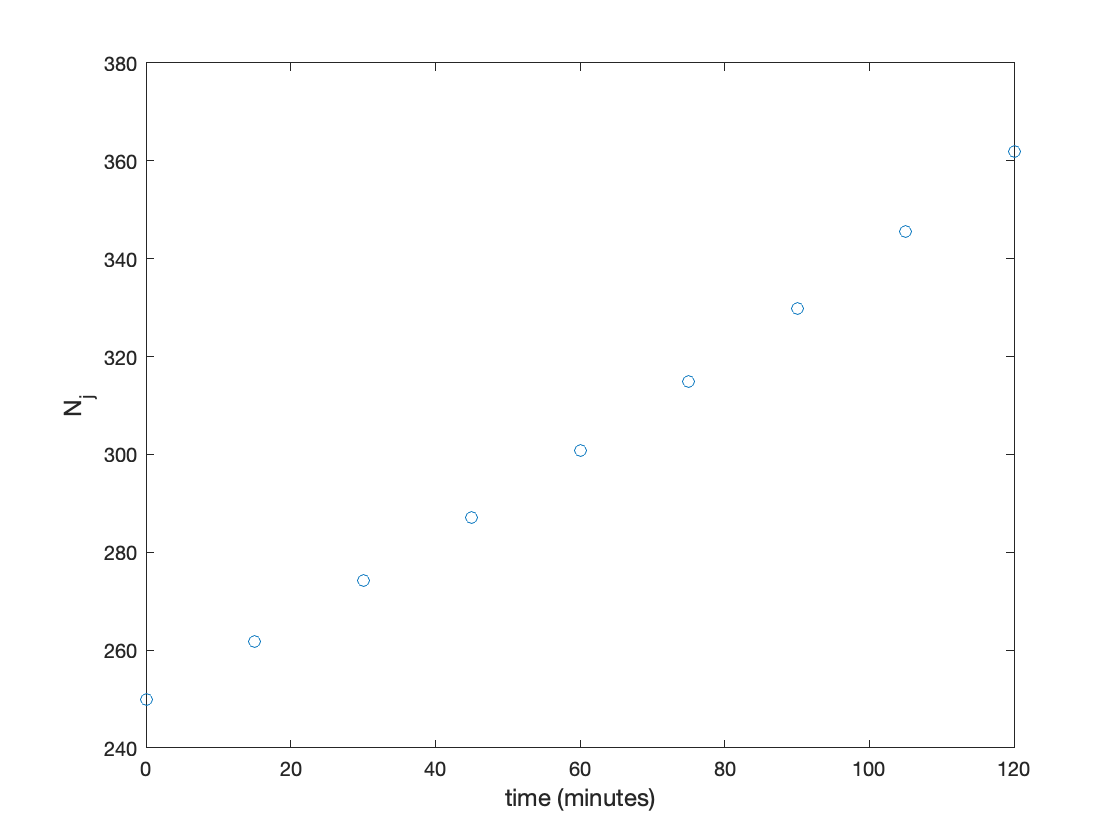


t3    = 0:15:120;
nt3   = length(t3);
N3    = zeros(1,nt3);
N3(1) = 250; % N0 = 250
for j=2:nt3,
     N3(j) = (1+R)*N3(j-1);
end

plot(t3,N3,'o') 
xlabel('time (minutes)','fontsize',12) 
ylabel('N_j','fontsize',12)

## **Exercise** 1.1.9

([section link](https://sysmic.ac.uk/textbook/1.1-bacterial-growth-1.html#1.1.3))

1. A colony of 10,000 E-coli bacteria halves its population every hour.

i) Write code to model the population. 

fun119 = @(t) 10000*exp(-1.1552e-2*t);

ii) How many hours would it take for the number of bacteria to fall below 100 members?

fun119(399) % 6.65 hours

ans = 99.5930

iii) Plot a graph showing how the population changes over this time.

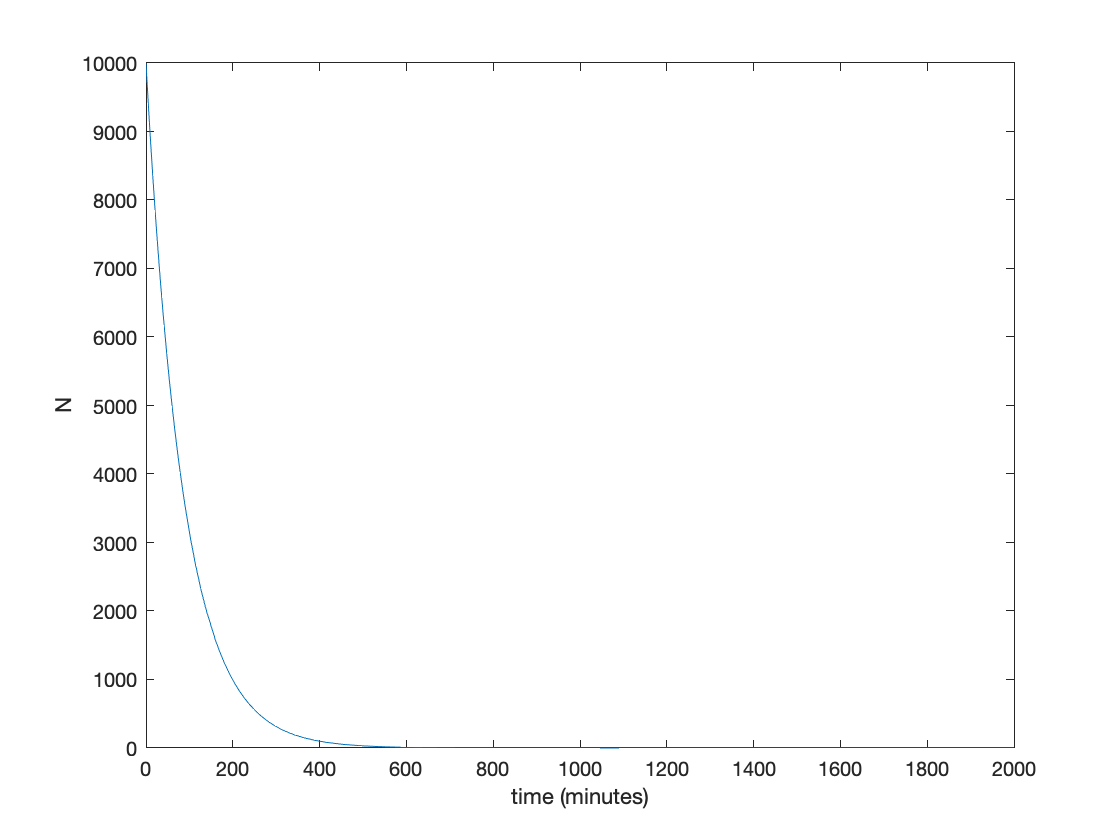

limits = [0 2000];
fplot(fun119,limits)
xlabel('time (minutes)')
ylabel('N')

## **Exercise** 1.1.11

([section link](https://sysmic.ac.uk/textbook/1.1-bacterial-growth-1.html#1.1.4))

1. The population of a bacteria colony can be modeled by the logistic growth function with parameters $r_{0\;} =0\ldotp 02$ and $K=20,000$. 

Write a MATLAB function to model the population and make a plot of the population over 10 hours for initial populations of 500, 10,000, and 80,000.

fun = @(t,r0,N0,K) K*N0*exp(r0*t)/(K-N0+N0*exp(r0*t)); 
fun1 = @(t) fun(t,0.02,500,20000)

fun1 = function_handle with value:
    @(t)fun(t,0.02,500,20000)


fun2 = @(t) fun(t,0.02,10000,20000)

fun2 = function_handle with value:
    @(t)fun(t,0.02,10000,20000)


fun3 = @(t) fun(t,0.02,80000,20000) 

fun3 = function_handle with value:
    @(t)fun(t,0.02,80000,20000)


limits = [0 600];
fplot(fun1,limits,'b')

hold on
fplot(fun2,limits,'r')

hold on
fplot(fun3,limits,'g')

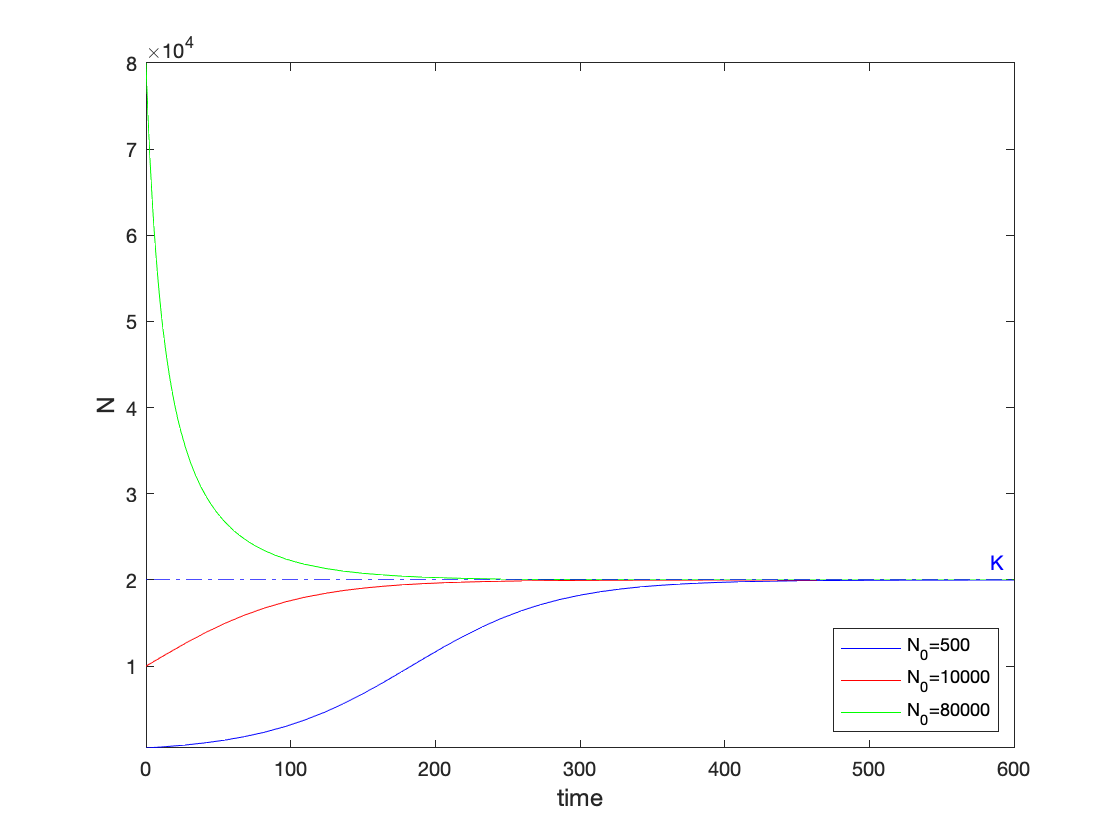

yline(20000, '-.b', 'K');
xlabel('time','fontsize',12)
ylabel('N','fontsize',12)
legend('N_0=500','N_0=10000','N_0=80000','Location','SouthEast')

2. Comment on the trend shown in the graph.

***Comments:***

% N0 = 500, The population increases slowly and picks up speed around 100

% mins reaching capacity at around 400 mins.

% N0 = 10000, The population increases steadily, reaching capacity at

% around 250 mins.

% N0 = 80000, Exponential decay within first 100 mins and plateauing at

% capacity around 250 mins.

3. If $r_0$ is increased how do these plots change?

***Comments:***

% If R0 increases, each curve reaches capacity sooner whilst if it

% decreases, the converse occurs and the growth/decay is much slower

% relatively.